
%DATA VISUALISATION

data1=table2cell(data);
gender=table2cell(data(:,1));
numeric = data{:,["Benign_malignant_cancer","Birth_control(Contraception)","blood","breast_pain","giving_birth","alcohol","age_FirstGivingBirth","abortion","age","weight","thickness_tumor","hereditary_history","marital_status","menopausal_age","menstrual_age","pregnency_experience","radiation_history","smoking","taking_blood_pressure_medicine","taking_gallbladder_disease_medicine","taking_heartMedicine"]};
R = corrcoef(numeric) ;
disp(R);

  Columns 1 through 4

    1.0000   -0.0555    0.0105    0.0328
   -0.0555    1.0000   -0.0319    0.0254
    0.0105   -0.0319    1.0000   -0.0531
    0.0328    0.0254   -0.0531    1.0000
   -0.0306    0.2894   -0.0046   -0.0765
   -0.0518    0.0093    0.0438    0.0027
    0.0170    0.2198    0.0154   -0.0662
   -0.1033    0.2771   -0.0801   -0.0092
   -0.0313    0.0352    0.0086   -0.0133
    0.0007   -0.0420   -0.0513    0.0473
   -0.0334    0.0300   -0.0135   -0.0051
    0.0246    0.0189   -0.0463    0.0346
   -0.0438    0.1651    0.0132   -0.0341
    0.0228    0.1418    0.0140    0.0114
   -0.0327    0.4609   -0.0542   -0.0834
   -0.0745    0.4073   -0.0270   -0.0232
   -0.0158    0.0419   -0.0007    0.0432
    0.0028   -0.0514    0.0211   -0.0287
    0.0911   -0.0215   -0.0251   -0.0487
   -0.0193   -0.0699   -0.0149   -0.0039
    0.0553   -0.0191    0.0128    0.0216

  Columns 5 through 8

   -0.0306   -0.0518    0.0170   -0.1033
    0.2894    0.0093    0.2198    0.2771
   -0.0046


%heatmap for correlation
colormap('autumn');
imagesc(R);
colorbar;
disp("1.Benign_malignant_cancer");

1.Benign_malignant_cancer


disp("2.Birth_control(Contraception)");

2.Birth_control(Contraception)


disp("3.breast_pain");

3.breast_pain


disp("4.giving_birth")

4.giving_birth


disp("5.alcohol");

5.alcohol


disp("6.age_FirstGivingBirth");

6.age_FirstGivingBirth


disp("7.abortion");

7.abortion


disp("8.age");

8.age


disp("9.weight");

9.weight


disp("10.thickness_tumor");

10.thickness_tumor


disp("11.hereditary_history");

11.hereditary_history


disp("12.marital_status");

12.marital_status


disp("13.menopausal_age");

13.menopausal_age


disp("14.menstrual_age");

14.menstrual_age


disp("15.pregnency_experience");

15.pregnency_experience


disp("16.radiation_history");

16.radiation_history


disp("17.smoking");

17.smoking


disp("18.taking_blood_pressure_medicine");

18.taking_blood_pressure_medicine


disp("19.taking_gallbladder_disease_medicine");

19.taking_gallbladder_disease_medicine


disp("20.taking_heartMedicine");

20.taking_heartMedicine


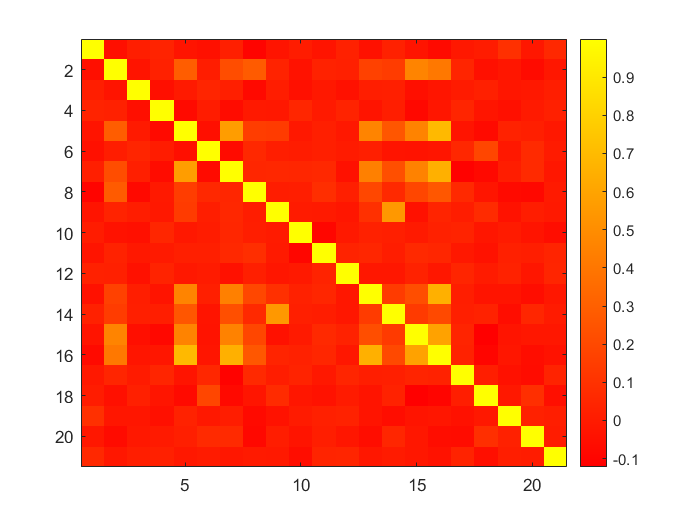

%plotting graph on relation between benign_malignant and taking heart
%medicines
x1=0;x2=0;x3=0;x4=0;
for i=1:length(gender)
    if(data1{i,24}==1 && data1{i,14}==1)
        x1=x1+1;
     end
    if(data1{i,24}==1 && data1{i,14}==0)
        x2=x2+1;
    end
    if(data1{i,24}==0 && data1{i,14}==1)
        x3=x3+1;
    end
    if(data1{i,24}==0 && data1{i,14}==0)
        x4=x4+1;
    end
end
bt=[x1,x2,x3,x4];
ax1 = nexttile;

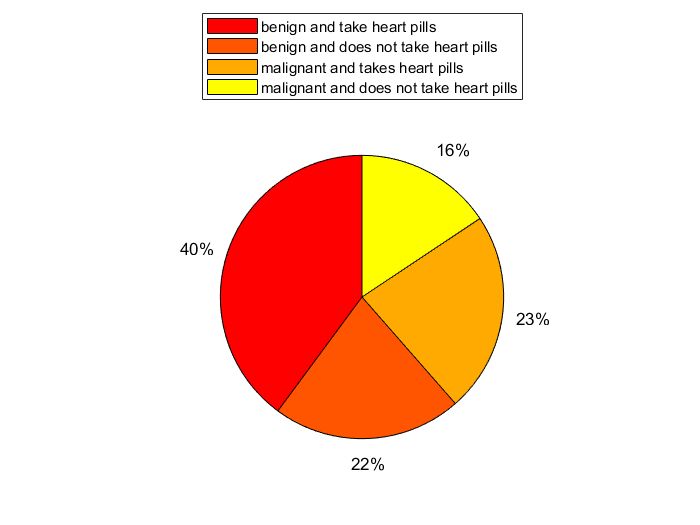

pie(ax1,bt);
labels = {'benign and take heart pills','benign and does not take heart pills','malignant and takes heart pills','malignant and does not take heart pills'};
lgd = legend(labels);
lgd.Layout.Tile = 'north';

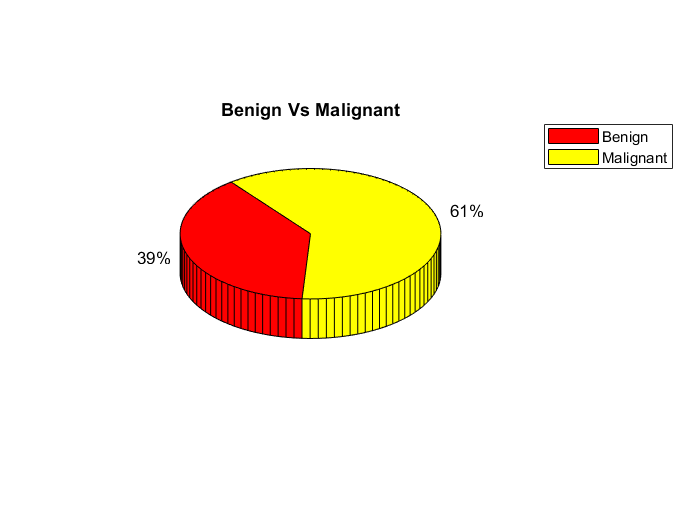


% benign vs Malign
Benign_malignant_cancer =table2cell(data(:,24));
b=0;
m=0;
for i=1:length(Benign_malignant_cancer)
    if(data1{i,24}==1)
        m=m+1;
    else
        b=b+1;
    end
end

Q = [b,m];

labels = {'Benign','Malignant'};
pie3(Q)
lgd = legend(labels);

title('Benign Vs Malignant');

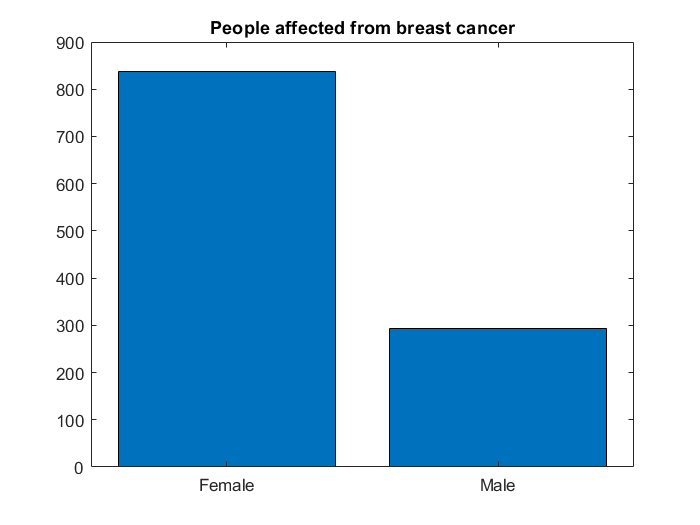



%plotting bar graph of people affected with breast cancer(gender-wise comparision)

m=0;
f=0;
for i=1:length(gender);
    if(data1{i,1}==1)
        m=m+1;
    else
        f=f+1;
    end
end

X = categorical({'Female','Male'});
X = reordercats(X,{'Female','Male'});
Y = [f,m];
bar(X,Y);
title("People affected from breast cancer");

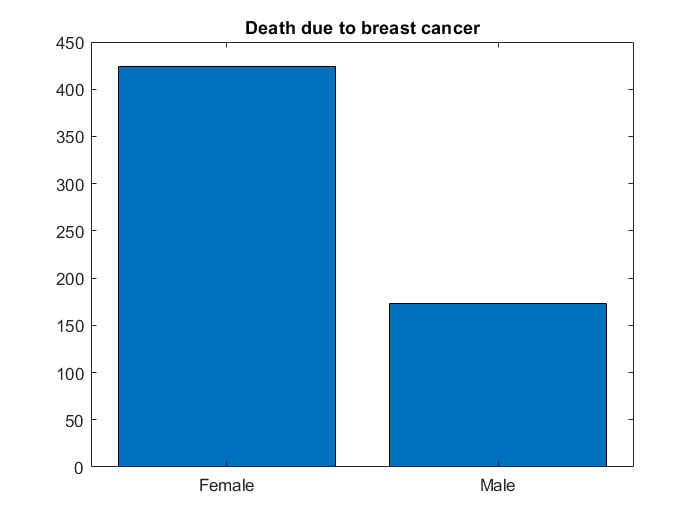


m=0;f=0;
%plotting graph of people who died(gender-wise)
for i=1:length(gender)
    if(data1{i,1}==1 && data1{i,25}=="death")
        m=m+1;
     end
    if(data1{i,1}==0 && data1{i,25}=="death")
        f=f+1;
    end
end
X = categorical({'Female','Male'});
X = reordercats(X,{'Female','Male'});
Y = [f,m];
bar(X,Y);
title("Death due to breast cancer");

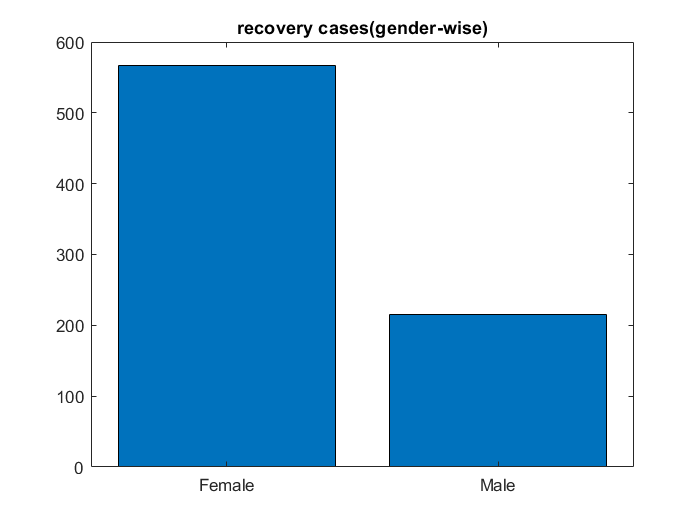


%recovered
for i=1:length(gender)
    if(data1{i,1}==1 && data1{i,25}=="recovered")
        m=m+1;
    end
    if(data1{i,1}==0 && data1{i,25}=="recovered")
        f=f+1;
    end
end
X = categorical({'Female','Male'});
X = reordercats(X,{'Female','Male'});
Y = [f,m];
bar(X,Y);
title("recovery cases(gender-wise)");

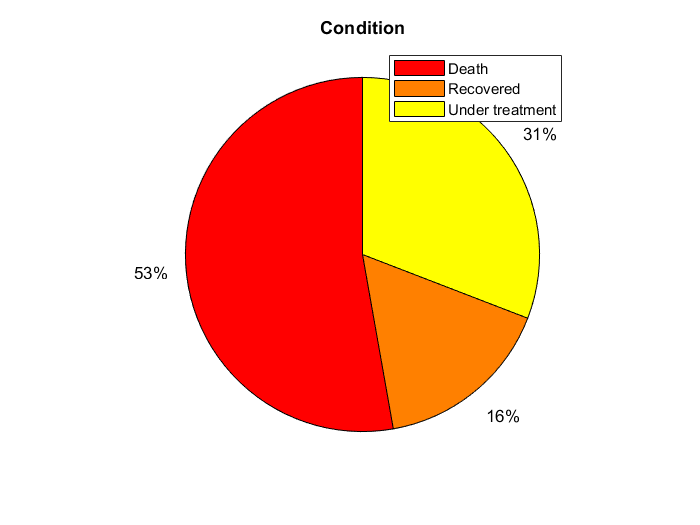


%plotting pie chart on condition
d=0;r=0;ut=0;
for i=1:length(gender)
    if(data1{i,25}=="death")
        d=d+1;
     end
    if(data1{i,25}=="recovered")
        r=r+1;
    end
    if(data1{i,25}=="under treatment")
        ut=ut+1;
    end
end

Con=[d,r,ut];
pie(Con);
title("Condition");
labels = {'Death','Recovered','Under treatment'};
lgd = legend(labels);

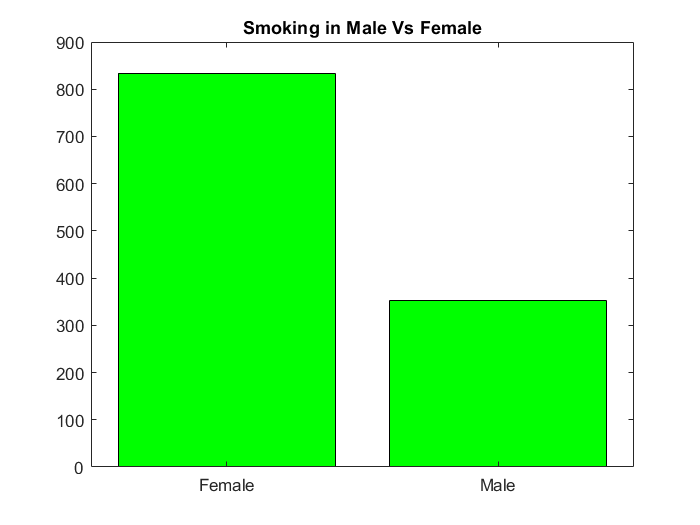


% smoking male Vs Female
for i=1:length(gender)
    if(data1{i,1}==1 && data1{i,17}==1)
        m=m+1;
    end
    if(data1{i,1}==0 && data1{i,17}==1)
        f=f+1;
    end
end
X = categorical({'Female','Male'});
X = reordercats(X,{'Female','Male'});
Y = [f,m];
bar(X,Y, 'green');
title('Smoking in Male Vs Female');

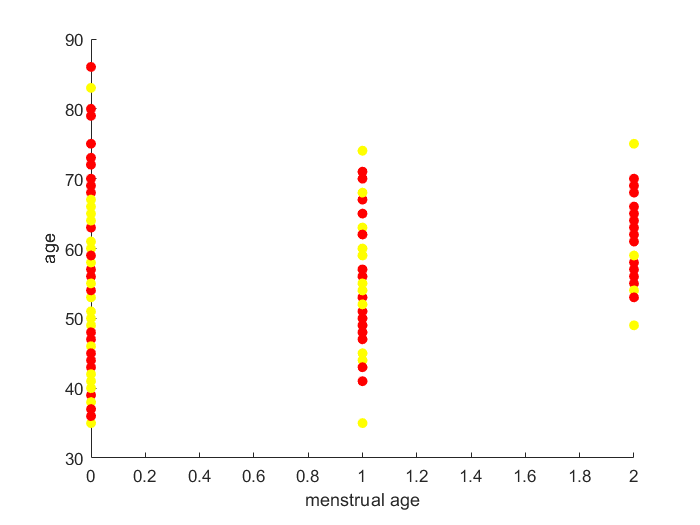



%plotting a scatter plot showing relation between menstrual_age, age and
%cancer type
c=[];
for i=1:length(gender)
    if(data1{i,24}==0)
         c(i)='r';
    else
         c(i)='b';
    end
end

%disp(c);
x=table2array(data(:,4));
y=table2array(data(:,23));
scatter(y,x,[],c,'filled')
xlabel("menstrual age");
ylabel("age");

disp("RED : Malignant");

RED : Malignant


disp("YELLOW : Benign");

YELLOW : Benign


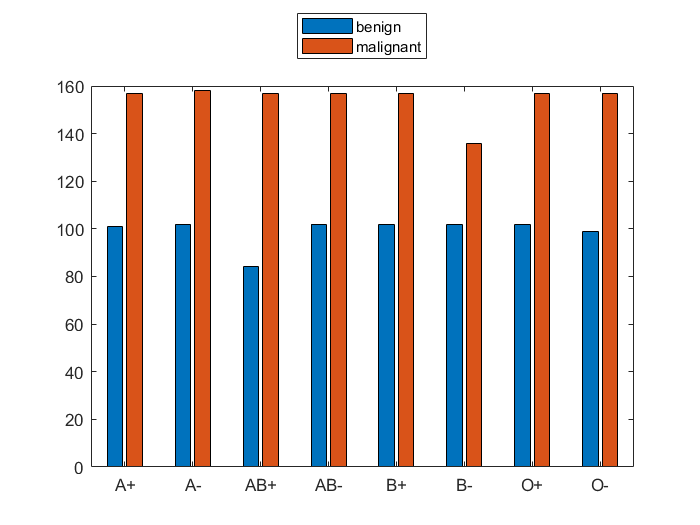


%grouped bar plot for relation between blood type and tumour type
apb=0;apm=0;anb=0;anm=0;abpb=0;abpn=0;abnb=0;abnm=0;bnp=0;bnm=0;bpb=0;bpm=0;opb=0;opm=0;onb=0;onm=0;
for i=1:length(gender)
    if(data1{i,13}==0 && data1{i,24}==0)
        apb=apb+1;
    end
    if(data1{i,13}==0 && data1{i,24}==1)
        apm=apm+1;
    end
    if(data1{i,13}==1 && data1{i,24}==0)
        anb=apb+1;
    end
    if(data1{i,13}==1 && data1{i,24}==1)
        anm=apm+1;
    end 
    if(data1{i,13}==2 && data1{i,24}==0)
        abpb=abpb+1;
    end
    if(data1{i,13}==2 && data1{i,24}==1)
        abpm=apm+1;
    end
    if(data1{i,13}==3 && data1{i,24}==0)
        abnb=apb+1;
    end
    if(data1{i,13}==3 && data1{i,24}==1)
        abnm=apm+1;
    end
    if(data1{i,13}==4 && data1{i,24}==0)
        bpb=apb+1;
    end
    if(data1{i,13}==4 && data1{i,24}==1)
        bpm=apm+1;
    end
    if(data1{i,13}==5 && data1{i,24}==0)
        bnb=apb+1;
    end
    if(data1{i,13}==5 && data1{i,24}==1)
        bnm=apm+1;
    end
    if(data1{i,13}==6 && data1{i,24}==0)
        opb=apb+1;
    end
    if(data1{i,13}==6 && data1{i,24}==1)
        opm=apm+1;
    end
    if(data1{i,13}==7 && data1{i,24}==0)
        onb=apb+1;
    end
    if(data1{i,13}==7 && data1{i,24}==1)
        onm=apm+1;
    end
end

ap=[apb,apm];
an=[anb,anm];
abp=[abpb,abpm];
abn=[abnb,abnm];
bp=[bpb,bpm];
bn=[bnb,bnm];
op=[opb,opm];
on=[onb,onm];
y=[ap;an;abp;abn;bp;bn;op;on];
X = categorical({'A+','A-','AB+','AB-','B+','B-','O+','O-'});
X = reordercats(X,{'A+','A-','AB+','AB-','B+','B-','O+','O-'});
bar(X,y);
labels = {'benign','malignant'};
lgd = legend(labels);
lgd.Layout.Tile = 'north';